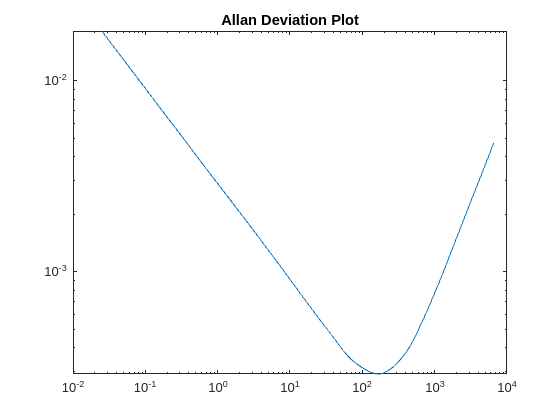

clear all;
close all;

% Sampling frequency
Fs = 40;

% Load data from the same file path
data = readtable('/home/febin/catkin_ws/src/analysis/allan_data.csv');

% Extract sensor data
field.IMU.orientation_x = data{:, 8};
field.IMU.orientation_y = data{:, 9};
field.IMU.orientation_z = data{:, 10};
field.IMU.orientation_w = data{:, 11};
field.IMU.linear_acc_x = data{:, 33};
field.IMU.linear_acc_y = data{:, 34};
field.IMU.linear_acc_z = data{:, 35};
field.IMU.gyro_x = data{:, 21};
field.IMU.gyro_y = data{:, 22};
field.IMU.gyro_z = data{:, 23};
field.IMU.magnetic_field_x = data{:, 48};
field.IMU.magnetic_field_y = data{:, 49};
field.IMU.magnetic_field_z = data{:, 50};

% Assuming linacc_z corresponds to angular rate
angular_rate = field.IMU.linear_acc_z;
string = 'Linear Acceleration - Z';

% Time step
t0 = 1 / Fs;

% Compute the cumulative sum
theta = cumsum(angular_rate, 1) * t0;

% Parameters for the Allan variance analysis
maxNumM = 100;
L = size(theta, 1);
maxM = 2^floor(log2(L / 2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m);
m = unique(m);

% Time intervals
tau = m * t0;

% Initialize arrays for Allan variance and Allan deviation
avar = zeros(numel(m), 1);

% Calculate the Allan variance
for i = 1:numel(m)
    mi = m(i);
    avar(i) = sum( ...
        (theta(1 + 2 * mi : L) - 2 * theta(1 + mi : L - mi) + theta(1 : L - 2 * mi)).^2, 1);
end

% Normalize by the formula
avar = avar ./ (2 * tau.^2 .* (L - 2 * m));

% Compute Allan deviation
adev = sqrt(avar);

% Plot the Allan deviation
figure
loglog(tau, adev)
title('Allan Deviation Plot');

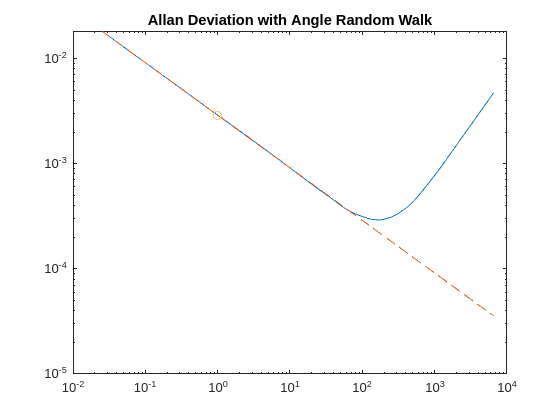


% Calculate other parameters and plot them
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

b = logadev(i) - slope * logtau(i);

logN = slope * log(1) + b;
N = 10^logN;

tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev, tau, lineN, '--', tauN, N, 'o');
title('Allan Deviation with Angle Random Walk');

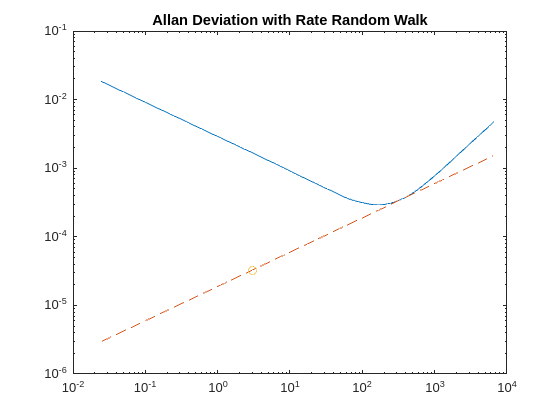


slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

b = logadev(i) - slope * logtau(i);

logK = slope * log10(3) + b;
K = 10^logK;

tauK = 3;
lineK = K * sqrt(tau / 3);
figure
loglog(tau, adev, tau, lineK, '--', tauK, K, 'o');
title('Allan Deviation with Rate Random Walk');

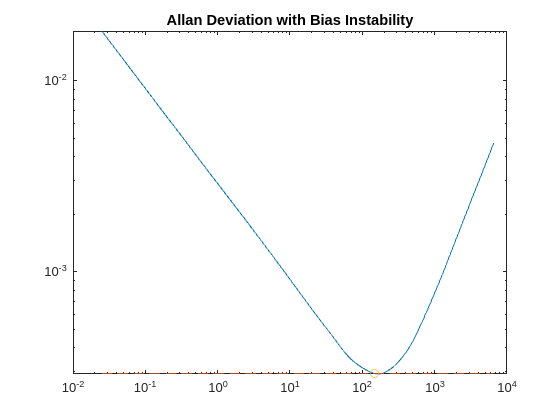


slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

b = logadev(i) - slope * logtau(i);

scfB = sqrt(2 * log(2) / pi);
logB = b - log10(scfB);
B = 10^logB;

tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev, tau, lineB, '--', tauB, scfB * B, 'o');
title('Allan Deviation with Bias Instability');

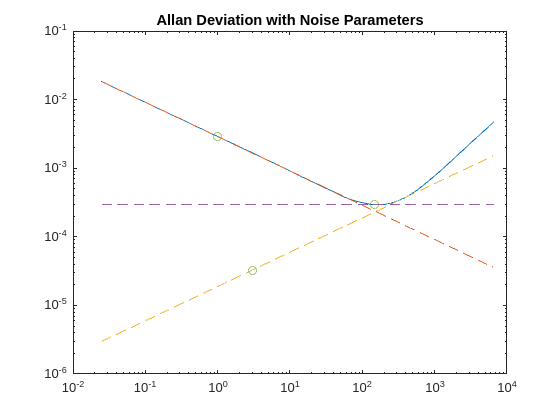


tauParams = [tauN, tauK, tauB];
params = [N, K, scfB * B];
figure
loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o');
title('Allan Deviation with Noise Parameters');


generateSimulatedData = true;

if generateSimulatedData

    gyro = gyroparams('NoiseDensity', N, 'RandomWalk', K, ...
        'BiasInstability', B);
    omegaSim = helperAllanVarianceExample(L, Fs, gyro);
else
    load('/home/febin/catkin_ws/src/analysis/allan_data.csv', 'omegaSim')
end

Running simulation 1 of 3 ...
Running simulation 2 of 3 ...
Running simulation 3 of 3 ...


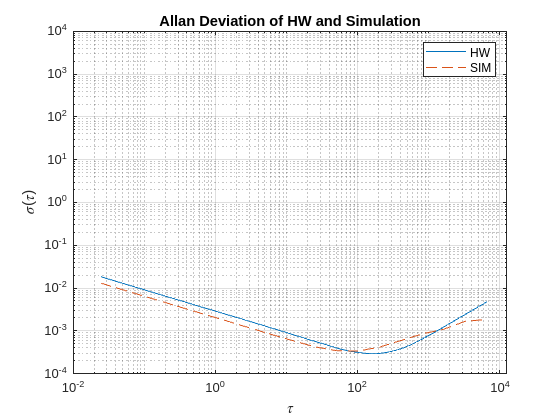


[avarSim, tauSim] = allanvar(omegaSim, 'octave', Fs);
adevSim = sqrt(avarSim);
adevSim = mean(adevSim, 2); 

figure
loglog(tau, adev, tauSim, adevSim, '--')
title('Allan Deviation of HW and Simulation')
xlabel('\tau');
ylabel('\sigma(\tau)')
legend('HW', 'SIM')
grid on
axis equal

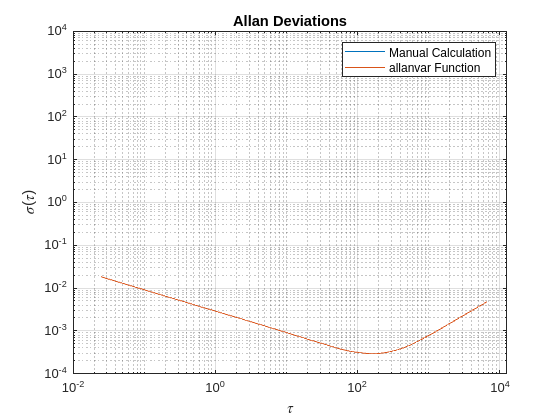


% Now, add the corrected section for the second figure
[avarFromFunc, tauFromFunc] = allanvar(angular_rate, m, Fs);
adevFromFunc = sqrt(avarFromFunc);

figure
loglog(tau, adev, tauFromFunc, adevFromFunc);
title('Allan Deviations');
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('Manual Calculation', 'allanvar Function')
grid on
axis equal